# Speed Polars

clc
clear all

A = 29;
e = 0.9;
W2S = 500; % Wing loading N/m^2
C_Lmax = 2.5;
gamma = 0;%linspace(1,3,101);
T_nonstand = 10; % Temperature offset deg C of non standard day
alt_des = 3000; % Desired altitude m
[rho,sigma_altnonstand] = Nonstandardrho(alt_des, T_nonstand);
Swet = 272; % ft^2 from DG 1000
f = 1.2; % ft^2 parasite area
C_D_0 = f/Swet;
r = Inf; % turn radius (m) -> set r = Inf for straight flight

C_L = linspace(0.25,C_Lmax,502);
C_D = (C_D_0 + C_L.^2 ./ (pi*A.*e));

V = sqrt(cosd(gamma) .* (1 ./ C_L) .* (2 ./ rho) .* W2S);

V_sink = -(C_D ./ C_L) .* V;
V_line = linspace(0,70,length(V));
%V_sinklin = Vsinklin(C_D_0, C_L, A, e, V_line); % this is what reanne originally had
V_sinklin = arrayfun(@(C_L) SinkRateCircle(C_L, C_D_0, A, e, W2S, rho, r), C_L)

V_sinklin =     1.2575    1.2309    1.2055    1.1813    1.1581    1.1359    1.1146    1.0943    1.0748    1.0561    1.0381    1.0209    1.0043    0.9884    0.9731    0.9584    0.9442    0.9306    0.9175    0.9048    0.8926    0.8808    0.8695    0.8585    0.8479    0.8377    0.8278    0.8183    0.8090    0.8001    0.7915    0.7831    0.7750    0.7672    0.7596    0.7523    0.7452    0.7383    0.7316    0.7251    0.7188    0.7127    0.7068    0.7010    0.6955    0.6901    0.6848    0.6797    0.6747    0.6699


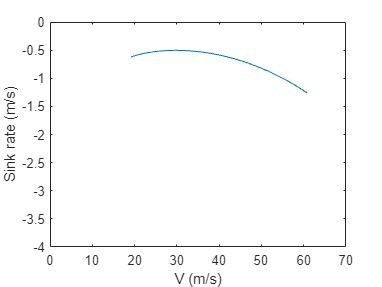


% Find tangent point

% Find tangent line point that meets the Sink speed line
% Note that the sink speed point that meets the tangent line has a specific C_L
% This specific C_L point must be found as it will be needed to make the
% slope constant for the tangent line

C_Lpt = linspace(0.0001,C_Lmax,502);
V_tanlineCLpt = -((C_D_0 + C_Lpt.^2 ./ (pi*A.*e)) ./ C_Lpt) .* V_line;
V_C_Lpt = sqrt(cosd(gamma) .* (1 ./ C_Lpt) .* (2 ./ rho) .* W2S);
V_sinktanCLpt = -((C_D_0 + C_L.^2 ./ (pi*A.*e)) ./ C_L) .* V_C_Lpt;

%% Find difference between V_sink and V_tanline
dif = abs(abs(V_tanlineCLpt) - abs(V_sinktanCLpt));
pt = find(dif <= 0.002);

V_tan = -((C_D_0 + C_Lpt(pt).^2 ./ (pi*A.*e)) ./ C_Lpt(pt)) .* V_line;
V_sinkpt = -((C_D_0 + C_Lpt.^2 ./ (pi*A.*e)) ./ C_Lpt) .*  sqrt(cosd(gamma) .* (1 ./ C_Lpt(pt)) .* (2 ./ rho) .* W2S);

plot(V,V_sink)

xlabel('V (m/s)')
ylabel('Sink rate (m/s)')
xlim([0,70])
ylim([-4,0])

hold on

% plot(V_line,V_tan)
% plot(V,V_sinkpt)

hold off

% CL demanded plot

## C_L as function of V

clc
clear all

A = 29;
e = 0.9;
W2S = 620; % Wing loading N/m^2
W2S = 500; % Wing loading N/m^2
C_Lmax = 2.5;
T_nonstand = 10; % Temperature offset deg C of non standard day
alt_des = 3000; % Desired altitude m
[rho,sigma_altnonstand] = Nonstandardrho(alt_des, T_nonstand);
%Swet = 410; %272; % ft^2 from DG 1000
%f = 1.2 % ft^2 parasite area
C_D_0 = 0.0109;%6.26 * 10^-4; %f/Swet;
V = 4:0.01:70;

C_L = 0.5 .* rho .* V.^2 .* (1/W2S);
C_D = (C_D_0 + C_L.^2 ./ (pi*A.*e));
V_sink = -(C_D ./ C_L) .* V;
dV_sink = gradient(V_sink,0.01);

% V_sink value of tangent line at V = 0 for each point on the curve
V_sinkValue = V_sink - V .* dV_sink;

% Find the V positions where V_sinkValue is close to origin
[~,pt] = mink(abs(V_sinkValue),1);

% Tangent line
V_sinktan = dV_sink(pt) .* (V - V(pt)) + V_sink(pt);

% Glide angle for best L/D
gamma = atand(V_sink(pt)/V(pt))

gamma = -1.3210

L_D = C_L(pt)/C_D(pt)

L_D = 43.3663

V_optimum = V(pt)

V_optimum = 29.5400

C_L_optimum = C_L(pt)

C_L_optimum = 0.9454

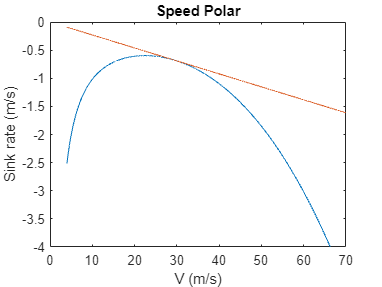


figure;

plot(V,V_sink)
hold on

plot(V,V_sinktan)

title('Speed Polar')
xlabel('V (m/s)')
ylabel('Sink rate (m/s)')
xlim([0,70])
ylim([-4,0])
%xline(V_optimum)

hold off